# Atividade 04 - Série Exponencial De Fourier 

## Boas Práticas:

clear;                  %%% limpando todas as variáveis
close all;              %%% fechando todas as figuras
clc;                    %%% limpando a tela

## Parte 01:

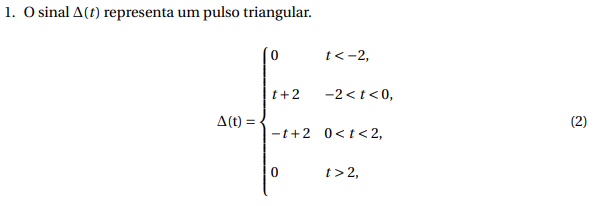

### Cálculo Analítico de Dn

Para determinar $D_n$ precisamos resolver a seguinte integral:

 
$$D_{n}=\frac{1}{T_{0}}\displaystyle\int_{0}^{T_{0}}g_{T_{0}}(t)e^{-jn\omega_{0}t}dt$$


Descrevendo o pulso de acordo com os intervalos:


$$D_{n}=\frac{1}{4}\left(\int_{-2}^0te^{-jn\omega_{0}t}dt \ + \ \int_{-2}^02e^{-jn\omega_0 t}dt \ -\int_0^{2}te^{-jn\omega_0t}dt \ + \ \int_0^22e^{-jn\omega_0t}dt\right)$$


Sabendo que:

- 
$$$\displaystyle \int2e^{-jn\omega_{0}t}dt=\frac{-2e^{jn\omega_0t}}{jn\omega_0}+C$$$


- 
$$$\displaystyle \int te^{-jn\omega_0t}dt \Longrightarrow \text{Integração por Partes} \Longrightarrow \frac{-te^{-jn\omega_0t}}{jn\omega_0}+\frac{e^{-jn\omega_0t}}{n^2\omega^2_0}+C$$$


Substituindo:


$$D_n=\frac{1}{4}\left[\left.\left(\frac{-te^{-jn\omega_0t}}{jn\omega_0}+\frac{e^{-jn\omega_0t}}{n^2\omega^2_0}\right)\right|_{-2}^0 +\left.\left(\frac{-2e^{jn\omega_0t}}{jn\omega_0}\right)\right |_{-2}^0 - \left.\left(\frac{-te^{-jn\omega_0t}}{jn\omega_0}+\frac{e^{-jn\omega_0t}}{n^2\omega^2_0}\right)\right |_0^2 + \left.\left(\frac{-2e^{jn\omega_0t}}{jn\omega_0}\right)\right |_0^2  \right]$$


Calculando os limites de integração:


$$D_n=\frac{1}{4}\left(\frac{1}{n^2\omega_0^2}-\frac{2e^{2jn\omega_0}}{jn\omega_0}-\frac{e^{2jn\omega_0}}{n^2\omega_0^2}-\frac{2}{jn\omega_0}+\frac{2e^{2jn\omega_0}}{jn\omega_0}+\frac{1}{n^2\omega_0^2}-\frac{e^{-2jn\omega_0}}{n^2\omega_0^2}+\frac{2e^{-2jn\omega_0}}{jn\omega_0}+\frac{2}{jn\omega_0}-\frac{2e^{-2jn\omega_0}}{jn\omega_0}\right)$$


Substituindo $\omega_0=\frac{2\pi}{T_0}=\frac{2\pi}{4}=\frac{\pi}{2}$ e assim simplificando:


$$D_n=\frac{1}{n^2\pi^2}-\frac{j}{n\pi}+\frac{1-e^{jn\pi}+jn\pi}{n^2\pi^2}-\frac{e^{-jn\pi}}{n^2\pi^2}$$


### Verificação do resultado de forma analítica

%%% Variáveis simbólicas
syms t n n_sym                 %%% t: variável de tempo; n e n_sym: numero de harmônicas


%%% Cálculo de Variáveis 
T0 = 4;                       %%% Período fundamental do sinal 
w0 = (2*pi)/T0;               %%% Frequência angular

%%% Cálculo de Dn:
Dn = (1/T0) * (int((t+2)*exp(-1j*n*w0*t),t,-2,0) + int((-t+2)*exp(-1j*n*w0*t),t,0,2))

$$Dn = \frac{1}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n\,\mathrm{i}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}}{n^{2}\,\pi^{2}}$$

### Potência do sinal

%%% Cálculo da potência
Pg = (1/T0) * (int((t+2)^2,t,-2,0) + int((-t+2)^2,t,0,2))

$$Pg = \frac{4}{3}$$

### Reconstrução do Sinal

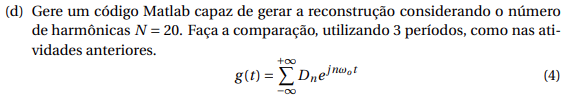

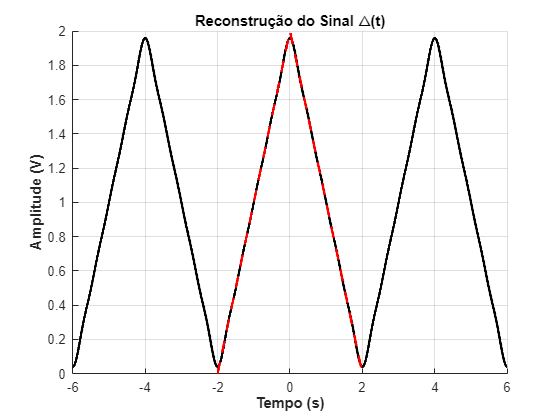

%%% Definição do número de harmônicas 
N = 10;
n = -N:1:N;                                                             %%% Vetor de índices harmônicos de -10 a 10

%%% Variáveis para o plot 1
tempo = -6:1e-3:6;                                                      %%% Vetor de tempo para o plot (mais de um período)
aux = 0;                                                                %%% Otimização do programa
Dn_plot = eval(Dn);                                                     %%% Valor numérico de Dn
Dn_plot(11) = (1/T0) * (int(t+2,t,-2,0) + int(-t+2,t,0,2));             %%% correção D_0 (eliminando a determinação, valor médio do sinal)

%%% Síntese do sinal g(t)
for k = 1:length(n)
    aux  =  aux + Dn_plot(k)*exp(1j * n(k) * w0 .* tempo);
end


%%% Plot do sinal sintetizado/ Plot do sinal original

%%% Definição do sinal no intervalo de um período
tempo_sinal = -2:1e-3:2;
%%% Geração do sinal original (pulso triangular) utilizando a função tripuls
delta_t = 2 * tripuls(tempo_sinal, 4);


%%% Configurações do plot 
figure;
hold on;
plot(tempo,real(aux),'LineWidth',2,"Color",'k');
plot(tempo_sinal,delta_t,'LineWidth',2,"Color",'r','LineStyle','--');
hold off

title('Reconstrução do Sinal △(t)');
xlabel('Tempo (s)','FontWeight','bold');
ylabel('Amplitude (V)','FontWeight','bold');
grid;

## Parte 02:

### Cálculo Analítico de Dn1

Aplicando a propriedade do deslocamento em Fourier, temos que:


$$D_{n_{g_1(t)}}=D_n\cdot e^{-2jn\omega_0}-D_n\cdot e^{-6jn\omega_0}=\left(e^{-2jn\omega_0}-e^{-6jn\omega_0}\right)\cdot D_n$$


Substituindo $\omega_0=\frac{\pi}{4}$ temos:


$$D_{n_{g_1(t)}}=(e^{-j n \frac{\pi}{2}} - e^{-3 j n \frac{\pi}{2}})\cdot \left(\frac{1}{n^2\pi^2}-\frac{j}{n\pi}+\frac{1-e^{jn\pi}+jn\pi}{n^2\pi^2}-\frac{e^{-jn\pi}}{n^2\pi^2}\right)$$


### Verificação do resultado de forma analítica

syms n;                      %%% Variável simbólica n
T1 = 8;                      %%% Define o novo período
w1 = (2*pi)/T1;              %%% Calcula a nova frequência angular 

%%% Propriedade de deslocamento para obter os coeficientes do sinal deslocado
Dn1_2 = Dn*(exp(-1i*n*w1*2)-exp(-1i*n*w1*6))

$$Dn1\_2 = -\left({\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}-{\mathrm{e}}^{-\frac{3\,\pi \,n\,\mathrm{i}}{2}}\right)\,\left(\frac{\mathrm{i}}{n\,\pi }-\frac{1}{n^{2}\,\pi^{2}}-\frac{1-{\mathrm{e}}^{\pi \,n\,\mathrm{i}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}+\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}}{n^{2}\,\pi^{2}}\right)$$

### Potência do Sinal

%%% Cálculo da potência média do sinal deslocado (g1(t))
Pg1 = (1/T1) * (int((t)^2, t,0,2) + int((-t+4)^2, t, 2, 6) + int((t-8)^2, t, 6, 8))

$$Pg1 = \frac{4}{3}$$

### Reconstrução de um Sinal

%%% Cálculo de Dn:
% Cálculo dos coeficientes Dn para o novo sinal g1(t)
Dn1 = (1/T1) * ( int((t+2)*exp(-1j*n*w1*t), t, -2, 0) + int((-t+2)*exp(-1j*n*w1*t), t, 0, 2) )

$$Dn1 = \frac{2}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{2-2\,{\mathrm{e}}^{\frac{\pi \,n\,\mathrm{i}}{2}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{2\,{\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}}{n^{2}\,\pi^{2}}$$

%%% Aplica os deslocamentos ao sinal
Dn1_d = Dn1*(exp(-2j*n*w1)-exp(-6j*n*w1))  

$$Dn1\_d = \begin{array}{l} -\left({\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}-{\mathrm{e}}^{-\frac{3\,\pi \,n\,\mathrm{i}}{2}}\right)\,\left(\frac{\mathrm{i}}{n\,\pi }-\frac{2}{\sigma_{1}}-\frac{2-2\,{\mathrm{e}}^{\frac{\pi \,n\,\mathrm{i}}{2}}+\pi \,n\,\mathrm{i}}{\sigma_{1}}+\frac{2\,{\mathrm{e}}^{-\frac{\pi \,n\,\mathrm{i}}{2}}}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=n^{2}\,\pi^{2} \end{array}$$

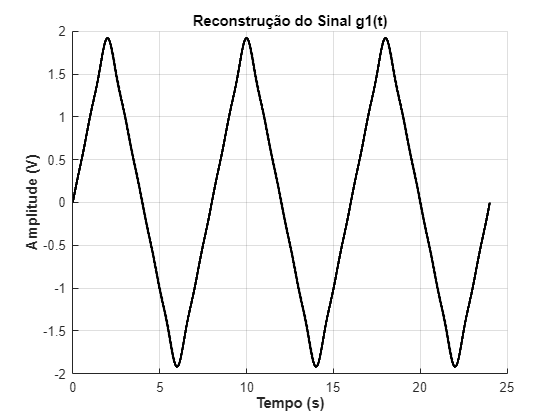

N = 10;                                                               %%% Define o número de harmônicas (10)
n = -N:1:N;                                                           %%% Cria o vetor de harmônicas

tempo2 = 0:1e-3:24;                                                   %%% Define o vetor de tempo para a reconstrução
Dn1num = eval(Dn1);                                                   %%% Valor numérico de Dn1
Dn1num(11) = (1/T1) * ( int(t+2, t, -2, 0) + int(-t+2, t, 0, 2) );    %%% Correção do coeficiente D0 para evitar indeterminação (valor médio)
Dn1_dnum = eval(Dn1_d);                                               %%% Avalia numericamente os coeficientes com deslocamento
Dn1_dnum(11) = 0;                                                     %%% Ajusta o coeficiente D0 (n = 0) para o sinal deslocado, definindo-o como zero
aux2 = 0;                                                             %%% Otimização

%%% Síntese do Sinal
for k = 1:length(n)

    aux2  =  aux2 + Dn1_dnum(k)*exp(1j * n(k) * w1 .* tempo2);

end


tempo_sinal2 = 0:1e-3:4;                                             %%% Define o vetor de tempo para um período do sinal g1(t)
delta_t_positivo = 2 * tripuls(tempo_sinal2, 4);                     %%% Gera o pulso original (deslocado) para comparação

%%% Configurações do plot
figure;
hold on;
plot(tempo2,real(aux2),'LineWidth',2,"Color",'k');

hold off
title('Reconstrução do Sinal g1(t)');
xlabel('Tempo (s)','FontWeight','bold');
ylabel('Amplitude (V)','FontWeight','bold');
grid;

## Parte 03

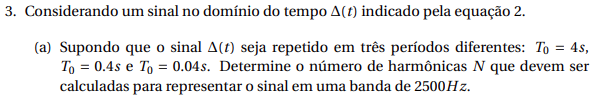

### Determinação do número de harmônicas

Errata) Onde se lê $T_{0}=0.4s$ e $T_{0}=0.04s$, leia-se: $T_{0}=40s$ e $T_{0}=400s$

Para determinar o número de harmônicas, basta que: $N=\frac{largura \ da \ banda}{frequência}$

Resolução:

1) $T_{0}=4s$:

Assim: $N=\frac{2500}{\frac{1}{4}}=10.000$ harmônicas

2) $T_{0}=40s$:

$N=\frac{2500}{\frac{1}{40}}=100.000$ harmônicas

3) $T_{0}=400s$:

$N=\frac{2500}{\frac{1}{400}}=1.000.000$ harmônicas

syms n t;                  %%% Variáveis simbólicas
banda = 25;                %%% Largura de banda para a reconstrução 

%%% Para T0 = 4s:
T0 = 4;                    
N1 = banda / (1 / T0)      %%% Número de harmônicas para T0 = 4s

N1 = 100

%%% Para T0 = 40s:
T0 = 40;
N2 = banda / (1 / T0)      %%% Número de harmônicas para T0 = 40s

N2 = 1000

%%% Para T0 = 400s:
T0 = 400;
N3 = banda / (1 / T0)      %%% Número de harmônicas para T0 = 400s

N3 = 10000

### Coeficientes de Fourier Dn e Plotagens

%%% Para T0 = 4s:

T0 = 4;                    %%% Período fundamental             
w0 = 2 * pi / T0;          %%% Frequência angular para T0 = 4s

%%% Cálculo simbólico para Dn em T0 = 4s
D1 = (1/4) * ( int((t + 2) * exp(-1j * n * w0 * t), t, -2, 0) + int((-t + 2) * exp(-1j * n * w0 * t), t,  0, 2) )

$$D1 = \frac{1}{n^{2}\,\pi^{2}}-\frac{\mathrm{i}}{n\,\pi }+\frac{1-{\mathrm{e}}^{\pi \,n\,\mathrm{i}}+\pi \,n\,\mathrm{i}}{n^{2}\,\pi^{2}}-\frac{{\mathrm{e}}^{-\pi \,n\,\mathrm{i}}}{n^{2}\,\pi^{2}}$$

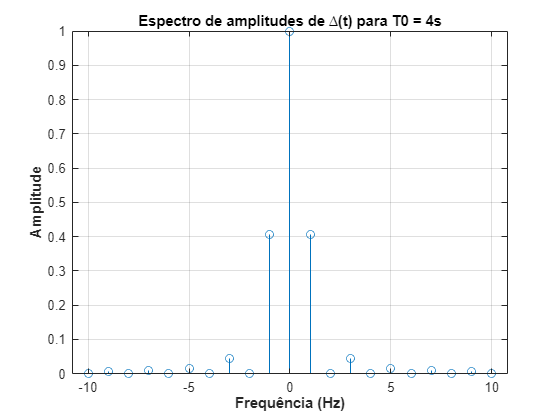

%%% Cálculo numérico para Dn em T0 = 4s
n = -10:1:10;                                                                  %%% Define o vetor de índices harmônicos de -10 a 10
amplitudes1 = abs(eval(D1));                                                   %%% Calcula o módulo dos coeficientes (espectro de amplitude)

%%% Ajustes para a plotagem 1
amplitudes1(11) = (1/4) * ( int(t + 2, t, -2, 0) + int(-t + 2, t, 0, 2) );     %%% Correção do coeficiente de ordem zero (n = 0)
freq = linspace(-10, 10, 21);                                                  %%% Cria o vetor de frequências para o plot

%%% Configurações do plot 1
figure;
stem(freq, amplitudes1), grid;  
title('Espectro de amplitudes de ∆(t) para T0 = 4s');
xlabel('Frequência (Hz)', 'FontWeight','bold');
ylabel('Amplitude', 'FontWeight','bold');

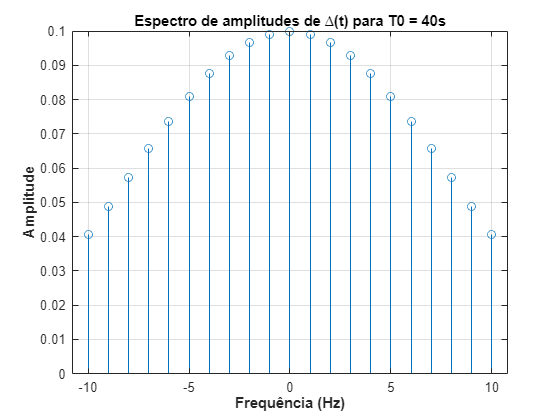

% Para T0 = 40s:
%%% Cálculo simbólico para Dn em T0 = 40s
D2 = (1 / 40) * ( int((t + 2) * exp(-1j * n * (w0 / 10) * t), t, -2, 0) + int((-t + 2) * exp(-1j * n * (w0 / 10) * t), t,  0, 2) );

%%% Cálculo numérico para Dn em T0 = 40s
amplitudes2 = abs(eval(D2));

%%% Ajustes para a plotagem 2
amplitudes2(11) = (1 / 40) * ( int(t + 2, t, -2, 0) + int(-t + 2, t, 0, 2) );    %%% Correção do coeficiente de ordem zero (n = 0)
freq = linspace(-10, 10, 21);                                                    %%% Cria o vetor de frequências para o plot

%%% Configurações do plot 2
figure;
stem(freq, amplitudes2), grid;
title('Espectro de amplitudes de ∆(t) para T0 = 40s');
xlabel('Frequência (Hz)', 'FontWeight','bold');
ylabel('Amplitude', 'FontWeight','bold');

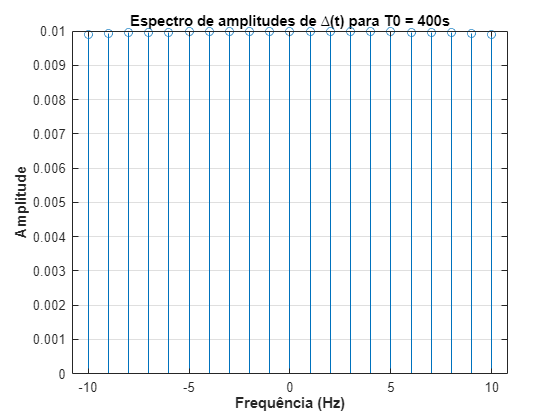

%%% Para T0 = 400s:
%%% Cálculo simbólico para Dn em T0 = 400s
D3 = (1/400) * ( int((t+2)*exp(-1j*n*(w0/100)*t), t, -2, 0) + int((-t+2)*exp(-1j*n*(w0/100)*t), t, 0, 2) );

%%% Cálculo numérico para Dn em T0 = 400s
amplitudes3 = abs(eval(D3));

%%% Ajustes para a plotagem 3
amplitudes3(11) = (1/400) * ( int(t+2, t, -2, 0) + int(-t+2, t, 0, 2) );    %%% Correção do coeficiente de ordem zero (n = 0)
freq = linspace(-10, 10, 21);                                               %%% Cria o vetor de frequências para o plot

%%% Configurações do plot 3
figure;
stem(freq, amplitudes3), grid;
title('Espectro de amplitudes de ∆(t) para T0 = 400s');
xlabel('Frequência (Hz)', 'FontWeight','bold');
ylabel('Amplitude', 'FontWeight','bold');

### Reconstrução do Sinal

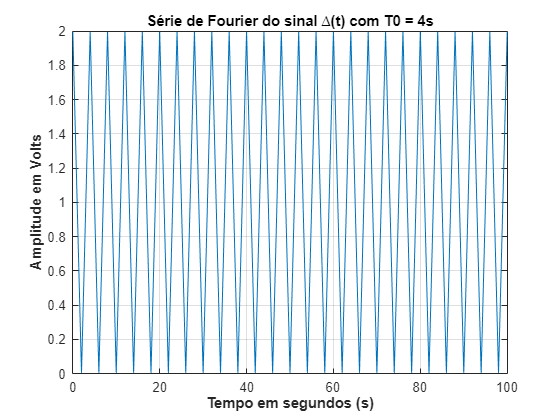

%%% Reconstrução para T0 = 4s:

syms n1;                    %%% Variável simbólica

%%% Cálculo simbólico para Dn em T0 = 4s 
D1_1 = (1/4) * ( int((t + 2) * exp(-1j * n1 * w0 * t), t, -2, 0) + int((-t + 2) * exp(-1j * n1 * w0 * t), t,  0, 2) );

%%% Cálculo numérico para Dn em T0 = 4s
n1 = -N1:1:N1;             %%% Define o intervalo de harmônicas 
D1n = eval(D1_1);

%%% Variáveis de Ajuste
D1n(N1 + 1) = (1 / 4) * ( int(t + 2, t, -2, 0) + int(-t + 2, t, 0, 2) );    %%% Correção do n = 0
tempo = 0:1e-3:100;                                                         %%% Tempo para a reconstrução
aux = 0;                                                                    %%% Otimização

%%% Síntese do sinal 
for k = 1:length(n1)
    aux = aux + D1n(k) * exp(1j * n1(k) * w0 .* tempo);
end

%%% Configurações do plot
figure;
plot(tempo, real(aux));
title('Série de Fourier do sinal ∆(t) com T0 = 4s');
xlabel('Tempo em segundos (s)', 'FontWeight','bold');
ylabel('Amplitude em Volts', 'FontWeight','bold');
grid;

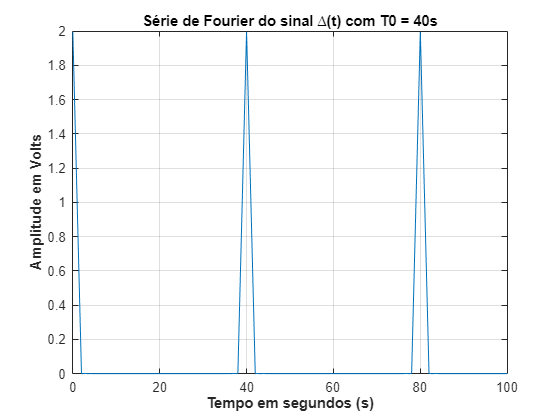

%%% Reconstrução para T0 = 40s:
syms n2;                    %%% Variável simbólica 

%%% Cálculo simbólico para Dn em T0 = 40s 
D2 = (1/40) * ( int((t + 2) * exp(-1j * n2 * (w0/10) * t), t, -2, 0) + int((-t + 2) * exp(-1j * n2 * (w0/10) * t), t, 0, 2) );

%%% Cálculo numérico para Dn em T0 = 40s
n2 = -N2:1:N2;             %%% Define o vetor de harmônicas
D2n = eval(D2);

%%% Variáveis de Ajuste
D2n(N2 + 1) = (1/40) * ( int(t + 2, t, -2, 0) + int(-t + 2, t, 0, 2) );   %%% Correção do n = 0
tempo2 = linspace(0, 100, 2*N2 + 1);                                      %%% Cria o vetor de tempo para a reconstrução
aux2 = 0;                                                                 %%% Otimização

%%% Síntese do sinal 
for k = 1:length(n2)
    aux2 = aux2 + D2n(k) * exp(1j * n2(k) * 2 * pi / 40 .* tempo2);
end 

%%% Configurações do plot
figure;
plot(tempo2, real(aux2));
title('Série de Fourier do sinal ∆(t) com T0 = 40s');
xlabel('Tempo em segundos (s)', 'FontWeight','bold');
ylabel('Amplitude em Volts', 'FontWeight','bold');
grid;

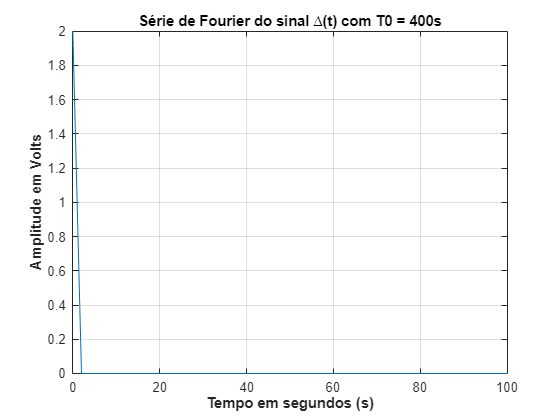

%%% Reconstrução para T0 = 400s:
syms n3;                    %%% Declara a variável simbólica n3

%%% Cálculo simbólico para Dn em T0 = 400s 
D3 = (1/400) * ( int((t + 2) * exp(-1j * n3 * (w0/100) * t), t, -2, 0) + int((-t + 2) * exp(-1j * n3 * (w0/100) * t), t, 0, 2) );

%%% Cálculo numérico para Dn em T0 = 400s
n3 = -N3:1:N3;             %%% Define o vetor de índices harmônicos para T0 = 400s
Dn3 = eval(D3);

%%% Variáveis de Ajuste
Dn3(N3 + 1) = (1/400) * ( int(t + 2, t, -2, 0) + int(-t + 2, t, 0, 2) );   %%% Correção do n = 0
tempo3 = linspace(0, 100, 2 * N3 + 1);                                     %%% Define o vetor de tempo para a reconstrução
aux3 = 0;                                                                  %%% Otimização        

%%% Síntese do sinal 
for k = 1:length(n3)
    aux3 = aux3 + Dn3(k) * exp(1j * n3(k) * 2 * pi / 400 .* tempo3);
end 

%%% Configurações do plot
figure;
plot(tempo3, real(aux3));
title('Série de Fourier do sinal ∆(t) com T0 = 400s');
xlabel('Tempo em segundos (s)', 'FontWeight','bold');
ylabel('Amplitude em Volts', 'FontWeight','bold');
grid;

### Potência

% Potência para T0 = 4s:
Pot_4 = (1/4) * ( int((t+2)^2, t, -2, 0) + int((-t+2)^2, t, 0, 2) )

$$Pot\_4 = \frac{4}{3}$$

% Potência para T0 = 40s:
Pot_40 = (1/40) * ( int((t+2)^2, t, -2, 0) + int((-t+2)^2, t, 0, 2) )

$$Pot\_40 = \frac{2}{15}$$

% Potência para T0 = 400s:
Pot_400 = (1/400) * ( int((t+2)^2, t, -2, 0) + int((-t+2)^2, t, 0, 2) )

$$Pot\_400 = \frac{1}{75}$$

### Energia

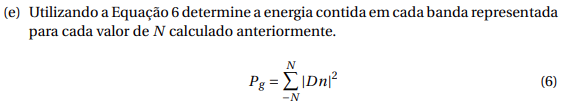

%%% Energia para T0 = 4s:
Pg_4 = 0;

for a = 1:length(n1)
    Pg_4 = Pg_4 + (abs(D1n(a)))^2;
end 

Pg_4  %%% Exibe a energia total calculada para T0 = 4s

Pg_4 = 1.3333

%%% Energia para T0 = 40s:
Pg_40 = 0;

for a = 1:length(n2)
    Pg_40 = Pg_40 + (abs(D2n(a)))^2;
end 

Pg_40  %%% Exibe a energia total para T0 = 40s

Pg_40 = 0.1333

%%% Energia para T0 = 400s:
Pg_400 = 0;

for a = 1:length(n3)
    Pg_400 = Pg_400 + (abs(Dn3(a)))^2;
end 

Pg_400  %%% Exibe a energia total para T0 = 400s

Pg_400 = 0.0133